# Example 2.14: Particle Size Distribution in Pharma Products

Note: this script reproduces Example 2.14 (Section 2.2.3) of **Statistics for Chemical Engineers**: particle sizes of a pharmaceutical product modeled as a lognormal RV. Victor Z UW-Madison, 2020 example log normal RV in pharma

clc; clear all; close all hidden;

## Data

generate data

mu=log(200)

mu = 5.2983

logq=log(400)

logq = 5.9915

alpha=0.9;
sigma=(logq-mu)/(sqrt(2)*erfinv(2*alpha-1))

sigma = 0.5409

x=linspace(10,1000,1000);
expF=[0.1 0.5 0.9];
expx=[95 200 411];

figure(1)

## Cdf

visualize cdf

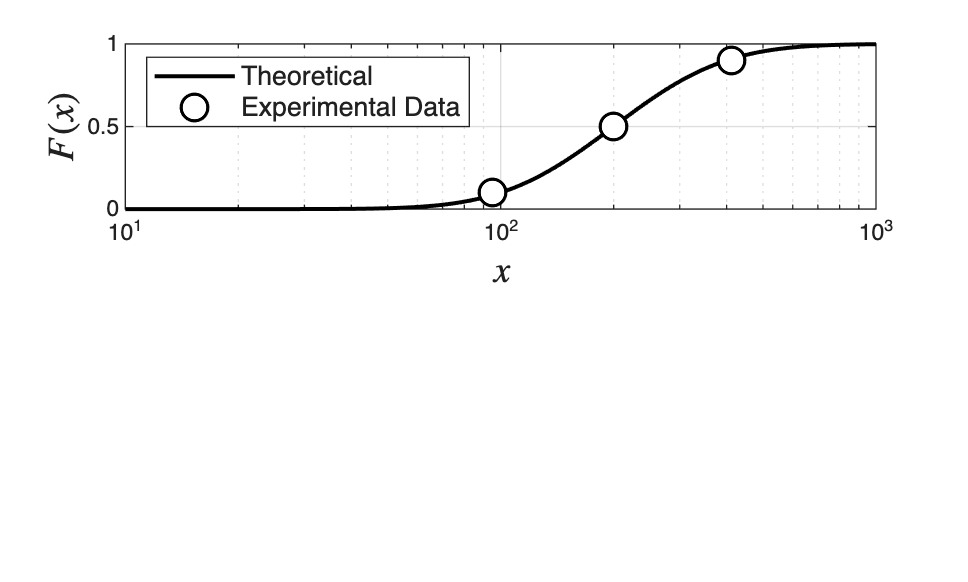

subplot(2,1,1)
semilogx(x,logncdf(x,mu,sigma),'black-','LineWidth',1.5)
hold on
plot(expx,expF,'blacko','MarkerFaceColor','white','MarkerEdgeColor','black','MarkerSize',10,'LineWidth',1.2) 
hold on
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
lgd=legend('Theoretical','Experimental Data','Location','northwest');
lgd.FontSize = 10;
title('')

## Pdf

visualize pdf

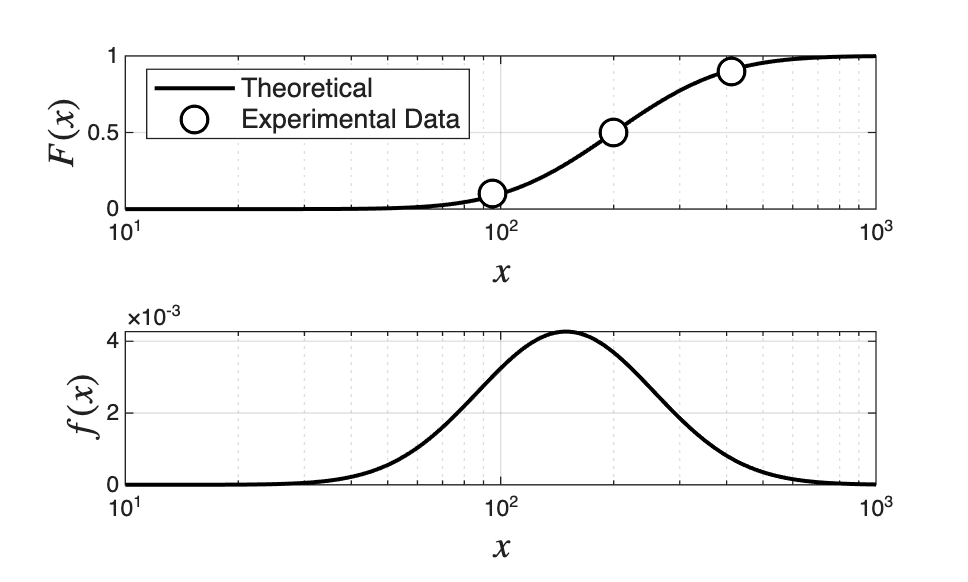

subplot(2,1,2)
semilogx(x,lognpdf(x,mu,sigma),'black-','LineWidth',1.5)
hold on
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
title('')
print -depsc ch2_lognormalpsd.eps

## Product in the desired size range

compute probability that 250<X<400

P=logncdf(400,mu,sigma)-logncdf(250,mu,sigma)

P = 0.2400

## Note

As in the book, estimating the amount of product in the desired range needs the theoretical model, because the data were not collected at the cdf values needed: models let us make predictions.